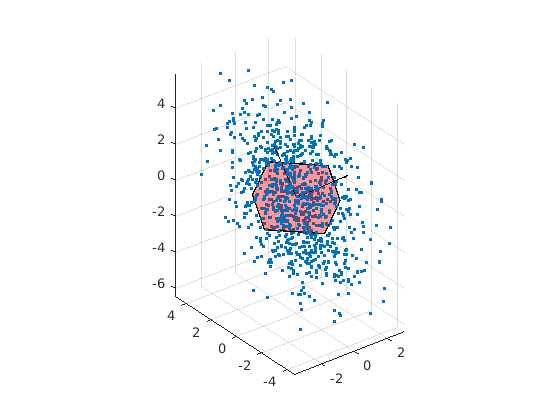

rng(982895489)
pwlregions_init


% Make a point cloud with these components
N = 1000;
c1 = [1;-1; 0];
c2 = [0.1; 1; 1.8];
c3 = [0.4; 0.7; 1];

% c1 = [1; 0; 0];
% c2 = [0;1;0];
% c3 = [0;0;1];

mu = [0,0,0];
sigma = [1,1.2,0.1];
coeffs = mvnrnd(mu,diag(sigma),N)';

points = c1*coeffs(1,:) + c2*coeffs(2,:) + c3*coeffs(3,:);


k = 2;  % number of components we want to keep
[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED] = pca(points');
plane = Polyhedron('He', [COEFF(:,3)',0]) & makebox(3,1.5);
x = randn(2,1000);
samples=COEFF(:,1).*x(1,:) + COEFF(:,2).*x(2,:);

clf;
axis([-5,5,-5,5,-5,5])
hold on;

scatter3(points(1,:), points(2,:), points(3,:), '.')
% scatter3(samples(1,:), samples(2,:), samples(3,:), '.')
quiver3(zeros(1,3),zeros(1,3),zeros(1,3),3*COEFF(1,:),3*COEFF(2,:),3*COEFF(3,:), 'k');
plot(plane, 'alpha', 0.4)
hold off;

axis equal

## Raising the dimension

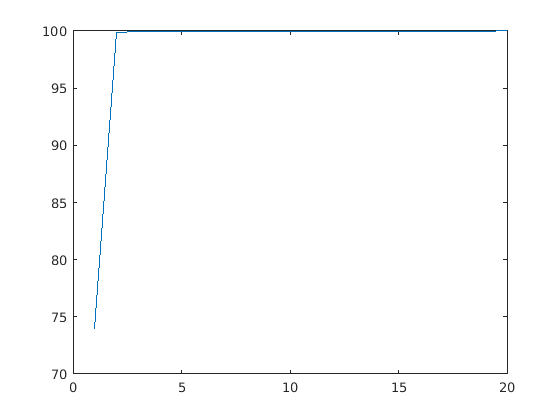


rng(9348954)
dim = 20;
more_points = [points ; 0.001*randn(dim-3,size(points,2))];

[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED] = pca(more_points');

plot(cumsum(EXPLAINED))


reduced_dim_points = COEFF'*more_points;


k = 2; % components to keep
hplane = Polyhedron('He', [COEFF(:,k+1:end)',zeros(dim-k,1)]) & makebox(dim,5);

rng(10); 
H = {randn(10,dim+1)}; 
tic; 
regs = partition_regions(hplane, H)

Array of 45 polyhedra.


toc

Elapsed time is 2.762162 seconds.



% Even though the dimensionality has been reduced significantly, this still
% takes much longer to compute because we're looking at higher dim space. I
% want to be able to transform the problem down to 2D and solve it there.
% How do I do this? The H representation of a hyperplane on some subspace
% can be found by just merging their H-representations. I guess that the
% next step is to choose a basis for the space, and then express the 


